% frequency shifting property 
M=10;
n=50;
n=1:M;
K=500;
% triangular window function
tri=unitseq(min(n),M,0).*(1-(M-1-2*n)/(M-1));
% dtft of triangular function using DTFT
[X,w]=dtft(tri,n,K);
%DTFT of triangular function using FFT
xf=fft(tri,1001);
xf=circshift(xf,ceil(length(w)/2))

xf =   -1.1106 - 0.0349i  -1.1106 + 0.0349i  -1.1065 + 0.1045i  -1.0983 + 0.1737i  -1.0860 + 0.2424i  -1.0697 + 0.3102i  -1.0494 + 0.3769i  -1.0252 + 0.4423i  -0.9973 + 0.5061i  -0.9656 + 0.5682i  -0.9302 + 0.6283i  -0.8914 + 0.6862i  -0.8493 + 0.7417i  -0.8040 + 0.7947i  -0.7556 + 0.8448i  -0.7043 + 0.8920i  -0.6504 + 0.9361i  -0.5939 + 0.9769i  -0.5352 + 1.0143i  -0.4743 + 1.0482i  -0.4116 + 1.0784i  -0.3471 + 1.1048i  -0.2813 + 1.1274i  -0.2142 + 1.1460i  -0.1461 + 1.1606i  -0.0773 + 1.1712i  -0.0080 + 1.1776i   0.0615 + 1.1800i   0.1311 + 1.1782i   0.2005 + 1.1723i   0.2693 + 1.1623i   0.3375 + 1.1482i   0.4047 + 1.1301i   0.4707 + 1.1080i   0.5352 + 1.0821i   0.5982 + 1.0523i   0.6592 + 1.0189i   0.7182 + 0.9819i   0.7748 + 0.9414i   0.8290 + 0.8977i   0.8804 + 0.8508i   0.9290 + 0.8009i   0.9746 + 0.7482i   1.0169 + 0.6928i   1.0559 + 0.6350i   1.0914 + 0.5750i   1.1232 + 0.5130i   1.1513 + 0.4491i   1.1756 + 0.3836i   1.1959 + 0.3169i


%Plot of DTFT value
figure('Name','DTFT Signal')
disp('DTFT Signal')

DTFT Signal


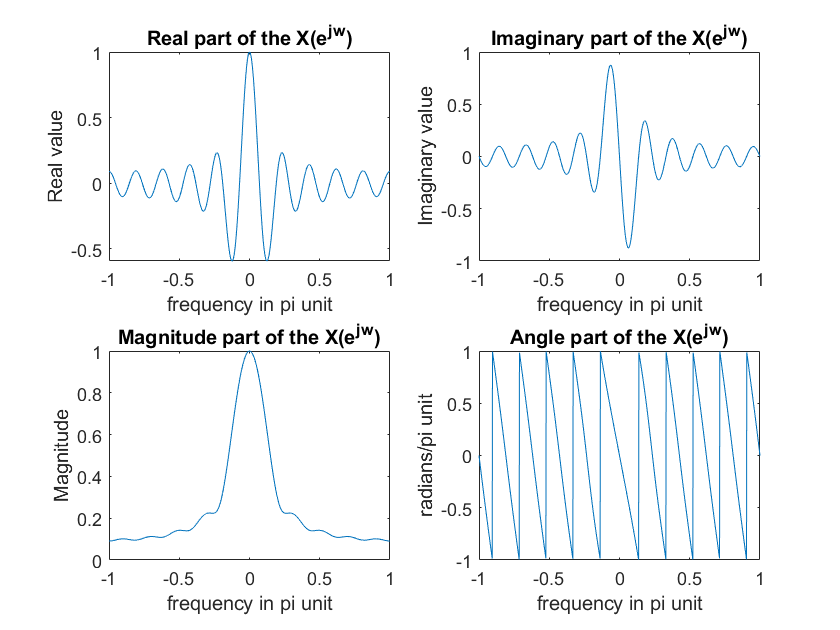

dfp4(X/max(X),w);

%Plot of FFT value
figure("Name",'fft')
disp('FFT')

FFT


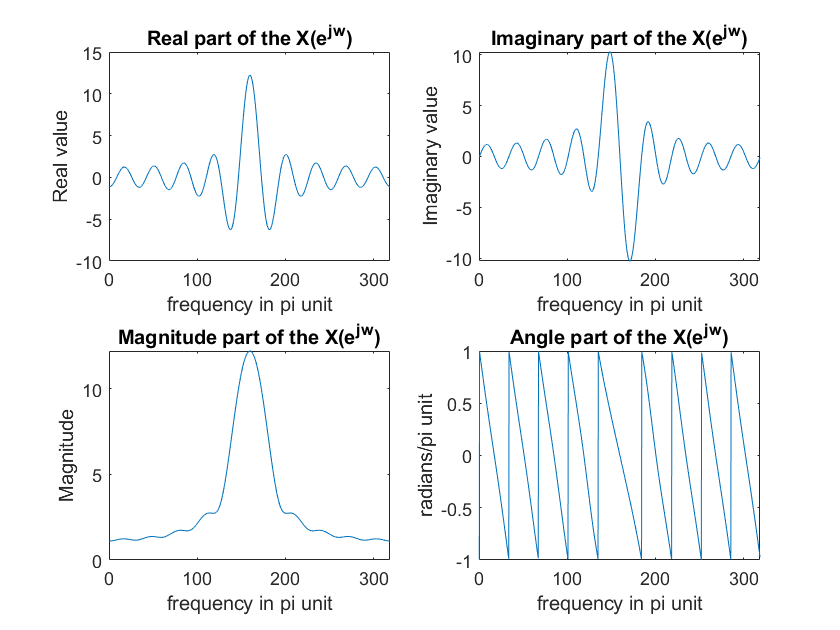

nf=1:1001;
dfp4(xf,nf)

% x=t*e^j*pi*n
x=tri.*exp(1j*pi.*n); % sample shifted by 1pi in time domain
%DTFT of x shifted by 1pi
[Xs,ws]=dtft(x,n,K);
figure("Name",'DTFT signal after right shifting by 1pi')
disp('DTFT signal after right shifting by 1pi')

DTFT signal after right shifting by 1pi


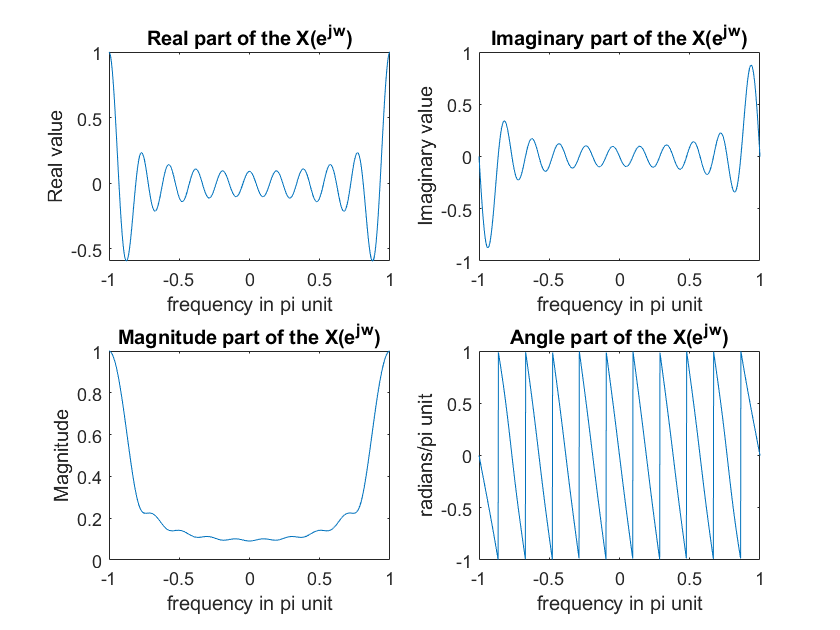

dfp4(Xs/max(Xs),ws)